# Анализ данных в MATLAB для начинающих

Проанализируем статистику цунами из Excel-файла в MATLAB без использования команд

## Главное окно MATLAB

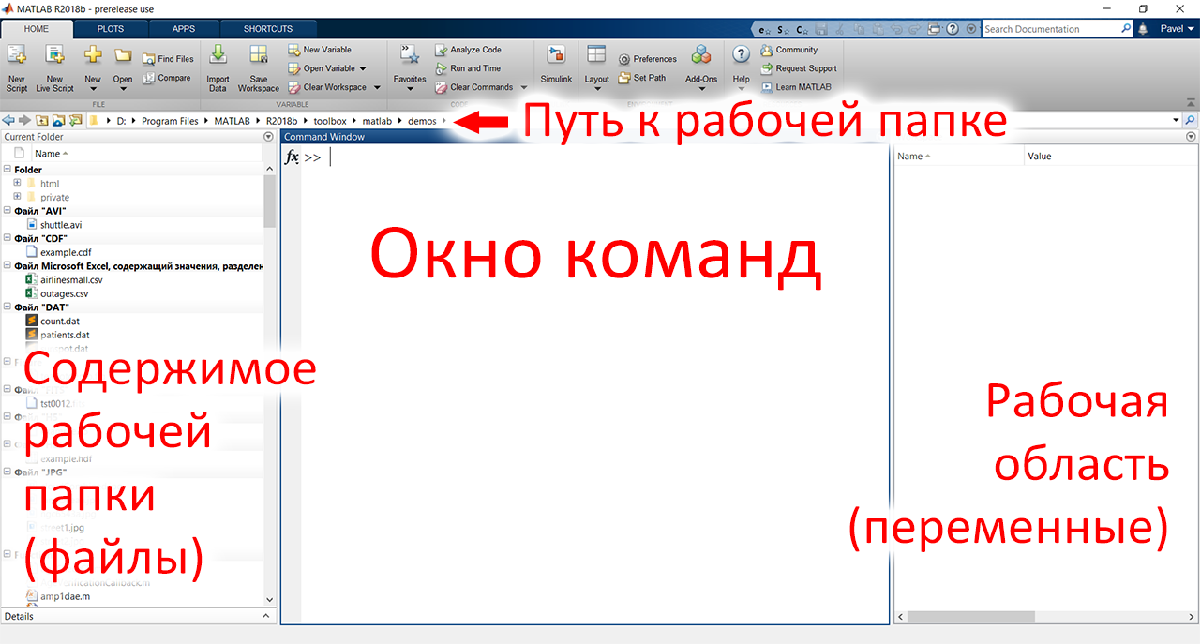

Центральную область занимает **окно команд**, сюда вы будете писать свои команды и тут же получать результат. Слева находится содержимое **текущей рабочей папки**, путь к ней задается в строке над окном команд (**путь к рабочей папке**). Это та папка, в которой для удобства лежат ваши рабочие файлы и ваши MATLAB-программы. В **рабочую область** будут выводиться все переменные MATLAB, с которыми вы работаете. 

## Импорт данных из файла Excel

### Поиск файла

Статистика цунами записана в файле `tsunamis.xlsx`, который идет вместе с MATLAB для примера и лежит в папке его установки. 

Откроем эту папку командой (**нажмите Ctrl+Enter**, чтобы выполнить код)

winopen(fullfile(matlabroot, 'toolbox\matlab\demos'))

Скопируем её путь, и вставим в строку **пути к рабочей папке** в главном окне, чтобы сделать папку рабочей и упростить доступ к файлу.

*Либо можно сменить путь командой*

Находим в окне **содержимого рабочей папки** файл `tsunamis.xlsx`, и кликаем по нему 2 раза, чтобы загрузить, откроется окно мастера импорта.

*Также открыть окно импорта нашего файла можно командой*

### Мастер импорта данных

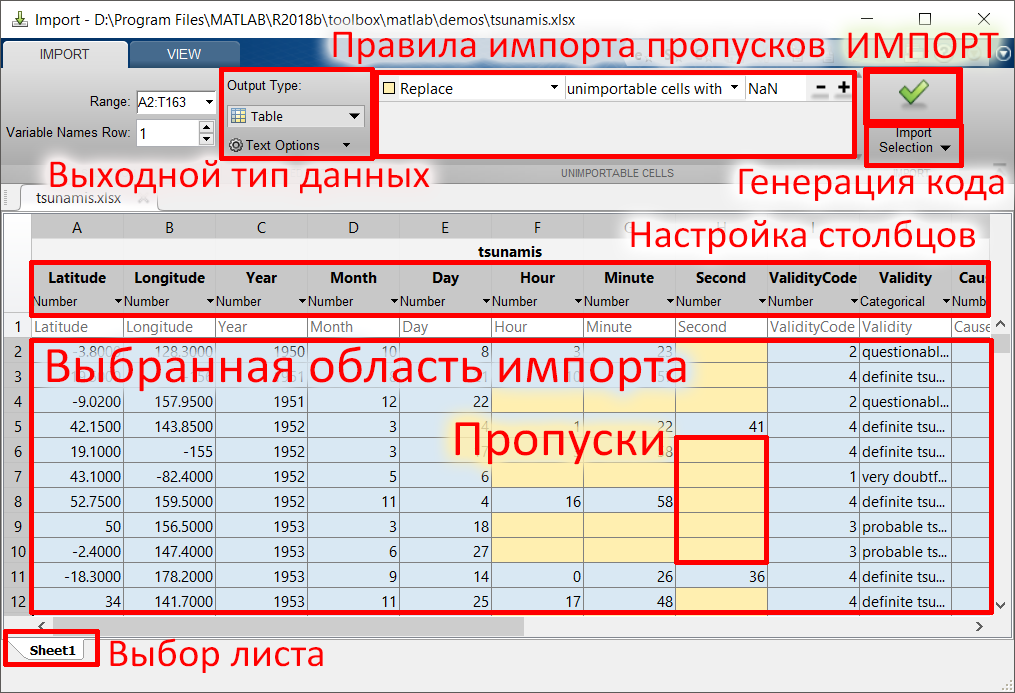

По виду он чем-то напоминает Excel, вы можете изучить данные и настроить параметры импорта. Например, вы можете вручную указать, какую часть таблицу хотите импортировать. По умолчанию она будет импортирована в переменную типа `table` - это самый удобный формат в MATLAB для хранения разнородных массивов данных. А у нас разные столбики имеют разный тип - число, категория, это может быть текст, дата или другой тип. Тип столбика можно поменять здесь же. Как и тип итоговой переменной. В таблице есть пропущенные значения, подсвеченные желтым, по-умолчанию они будут заменены на значение NaN (Not a Number).

После настройки жмем зеленую кнопку и получаем переменную `tsunamis`, с которой будем работать. Обратите внимание, что под кнопкой импорта есть дополнительные функции. Мы можем сгенерировать MATLAB скрипт или функцию, которая автоматически сделает все то, что мы настроили мышкой и выдаст такую же переменную. Таким образом мы можем свою работу автоматизировать и применить полученную функцию к другим файлам с такой же структурой.

## Анализ данных

### Работа с переменной

После импорта в **рабочей области** главного окна появилась переменная `tsunamis`. Откроем её двойным кликоми и изучим таблицу, которая в ней хранится.

*Также переменную можно открыть командой*

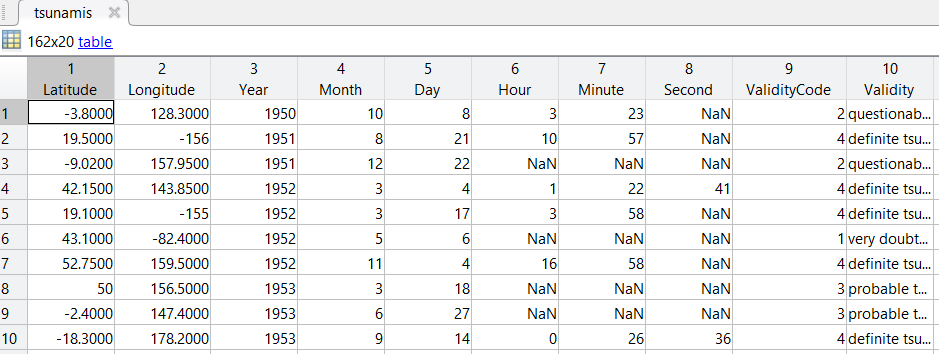

Видим что переменная имеет тип данных `table`, т.е. таблица, 162 строчки, т.е. измерения, и 20 столбцов, т.е. параметров цунами. Каждый столбик имеет свое название, считанное из исходной таблицы.

С таблицей можно работать с помощью мышки и клавиатуры. Например, можно изменять значения в ячейках (заменять пропуски). Можно переименовать или поменять местами столбцы, удалить лишние, вставить новые. Так же можно вставлять и удалять строки. По любому столбцу можно сортировать всю таблицу. 

Обратите внимание, что все манипуляции с таблицей отражаются в виде кода в окне команд. Таким образом MATLAB подталкивает нас к освоению команд. А ещё мы можем копировать эти команды и использовать в алгоритмах.

*Кстати, считать таблицу можно командой:*

tsunamis = readtable('tsunamis.xlsx');
tsunamis.Country = categorical(tsunamis.Country);

Вывести для ознакомления первые несколько строк таблицы можно командой `head`:

head(tsunamis)

ans = 8×20 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode           Validity            CauseCode         Cause          EarthquakeMagnitude        Country                Location            MaxHeight    IidaMagnitude    Intensity    NumDeaths    DescDeaths
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _______________________    _________    ________________<

*После ручной сортировки по столбцу *`Year`* прописывается команда*

tsunamis = sortrows(tsunamis,'Year','ascend');

*После ручного удаления столбца Second прописывается*

tsunamis = removevars(tsunamis, 'Second');

### Построение графиков

В переменной `tsunamis` выделим столбец `MaxHeight`, кликнув на его заголовок. Затем в главном окне MATLAB на вкладке **PLOTS** кликаем на график **plot**. Получаем простой график, где по оси абсцисс отложены порядковые номера точек, по оси ординат - значения столбца `MaxHeight`.

*При этом прописывается команда*

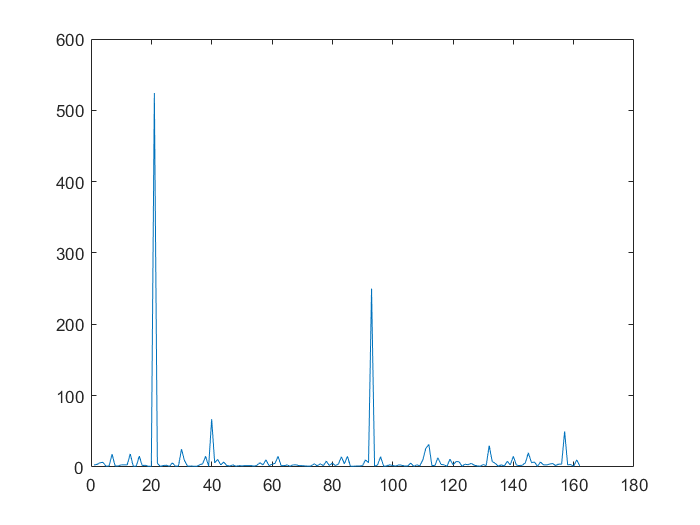

plot(tsunamis.MaxHeight)

Теперь выделим столбец `Year` и с зажатой клавишей Сtrl выделим также `MaxHeight`. Для двух выделенных столбцов на кладке **PLOTS** доступен график **scatter**, построим его.

*При этом прописывается команда*

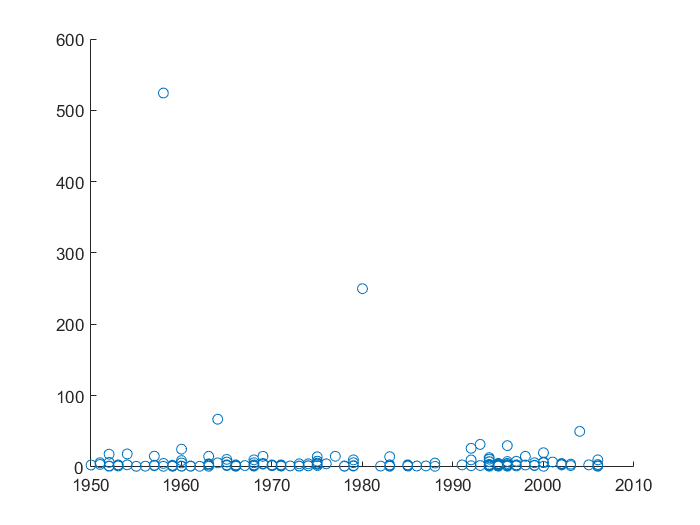

scatter(tsunamis.Year,tsunamis.MaxHeight)

График можно настроить, например, выбрав *Insert -> Title*, подписать его.

В меню *File -> Save As...* график можно сохранить на диск, чтобы потом, например, вставить в отчет.

Кроме того, *выбрав File -> Generate Code...*, вы получите MATLAB-код, который строит в точности такой же график со всеми настройками и оформлением.

Теперь выделим 3 столбца (с зажатым Ctrl): `Latitude`, `Longitude`, `MaxHeight`. Строим график **geobubble** (на вкладке **PLOTS**).

*При этом прописывается команда*

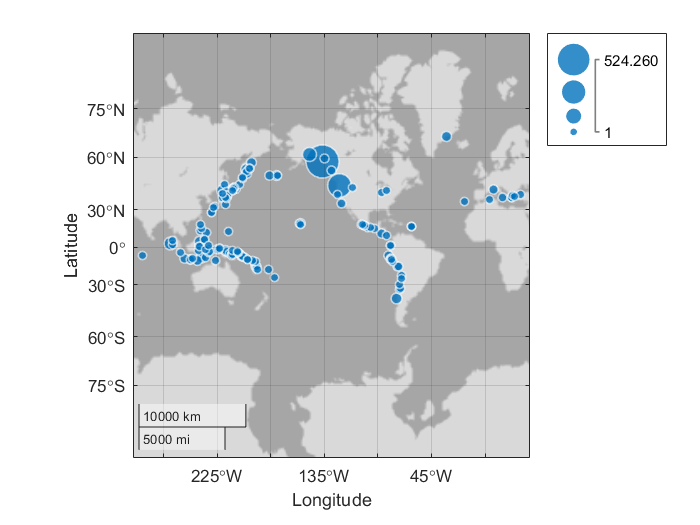

geobubble(tsunamis.Latitude,tsunamis.Longitude,tsunamis.MaxHeight);

Карта позволяет проанализировать, где цунами случаются чаще всего, и где они самые высокие.

Выделим столбец **Country** и построим график **wordcloud**.

*При этом прописывается команда*

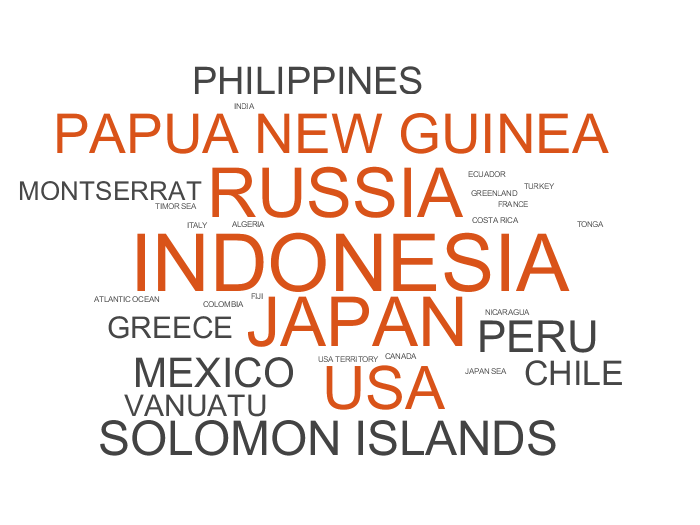

wordcloud(tsunamis.Country);

Облако слов наглядно показывает, в каких странах цунами наблюдаются чаще всего.

Оценим количественно, построив гистограмму - график **histogram**.

*При этом прописывается команда*

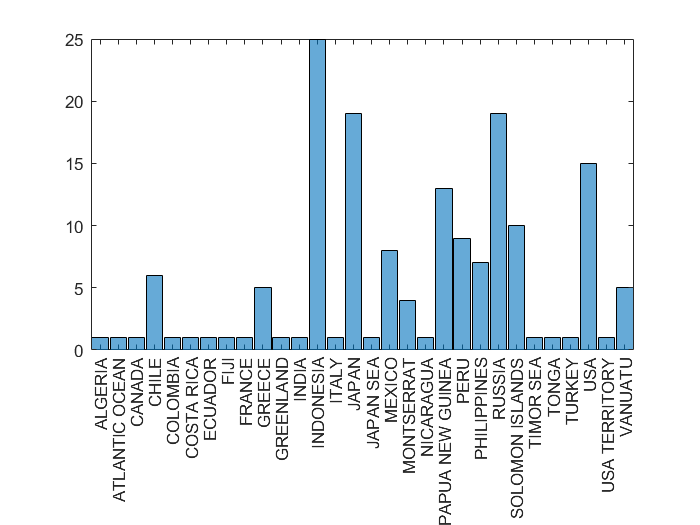

histogram(tsunamis.Country)

В России с 1950 по 2006 года было зафиксировано 19 цунами.

## Сохранение результатов работы

Если закрыть MATLAB, переменная `tsunamis` удалится. Чтобы сохранить её на диск можно на складке **HOME** нажать кнопку **Save Workspace**, при этом все переменные из **рабочей области** будут сохранены в файл с расширением *.mat*.

*Сохранить все переменные в файл matlab.mat в текущую рабочую папку можно также командой*

Чтобы загрузить все данные из .mat-файла, надо на него 2 раза кликнуть в окне **содержимого рабочей папки**.

*Загрузить данные из файла matlab.mat можно также командой*

*Pavel Roslovets, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2019*